# Cargar información de NDVI RH26

## Declaracion de variables sobre el área de estudio

import matlab.io.hdfeos.*
clearvars -except study_area;

%directorio de datos
dir_data = "D:\DATA\";
modis_product = 'MOD13A2';
kml_file = "RH26";

### Obtener la lista de archivos del producto

info_hdf = f_infohdfs2table(dir_data,modis_product);

>>>>> Obteniendo información de archivos sobre fechas ... 
>>>>> Analizando 1078 archivos


[num_registros_totales,~] = size(info_hdf);

#### Ventana para el mapa region hidrografica rio panuco

y coordenadas de la matriz de datos

[lon_mapa,lat_mapa] = f_get_map_window(dir_data,kml_file,0.1);

[coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam,ndvi_tam]...
    = f_get_coordinates(dir_data,kml_file,modis_product,info_hdf,0.09);

>>>>> Obteniendo la zona de estudio
D:\DATA\MOD13A2\061\*.hdf
>>>>> Analizando 1078 archivos


#### Obtener latitud y longitud

if (num_registros_totales > 0)
    % Obtener matrices de latitud y longitud
    [lat,lon,ndvi] = f_get_latlon(info_hdf,coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);
end

>>>>> Obteniendo latitud y longitud


## Crear el área de estudio

study_area = f_get_study_area(dir_data,kml_file,lat,lon,modis_product,ndvi_tam);

>>> Cargando área de estudio
>>> Área de estudio existente 1


ndvi = double(ndvi) .* 0.0001;

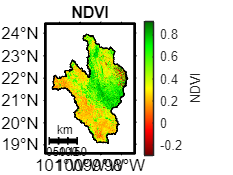

ndvi(study_area==false)=nan;
figure;
f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi,"NDVI",[],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');

disp("a");

a


## Leer los arreglos de datos

% Realizar la consulta de los datos que se requieren
tmp = find(  info_hdf.anio >=2000 );
info_consulta = info_hdf(tmp,:);

[num_registros,~] = size(info_consulta);

% arreglo 3d de ndvi por día
arr_ndvi = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d para la calidad del pixel
arr_ndvi_qa = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
arr_ndvi_nan = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

% arreglo 3d de ndvi por día con media juliana
arr_ndvi_sgf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);
% arreglo 3d de ndvi por día con media juliana
arr_ndvi_lf = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);

% arreglo 3d de ndvi por día con media juliana
arr_ndvi_mj = zeros( ndvi_tam(1),ndvi_tam(2) ,num_registros);


#### Leer los datos

bp=waitbar(0,'Obteniendo información de archivos MODIS'); 
for i=1:num_registros
    [ndvi,~,~,disponibilidad] = f_get_ndvi(info_consulta(i,:),coord_1k_v6_inicio,coord_1k_v6_tam,coord_1k_v7_inicio,coord_1k_v7_tam);

    % recortar el area de estudio
    %ndvi(study_area==false)=NaN;
    %disponibilidad(study_area==false)=NaN;

    %almacenar en el arreglo en 3d
    arr_ndvi(:,:,i) = ndvi;
    arr_ndvi_qa(:,:,i) = disponibilidad;
 
    arr_ndvi_mj(:,:,i) = ndvi;

    %barra de progreso
    waitbar(i/num_registros,bp,sprintf('Obteniendo información de archivos MODIS (%3.0f%%) ',(i/num_registros*100)));
end
close(bp); 


#### Mostrar el promedio de NDVI

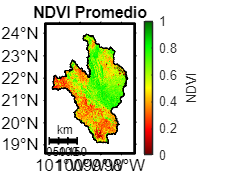

ndvi_prom = m_mean_3dpp(arr_ndvi);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI Promedio",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');

## Asegurar la calidad con media juliana

%Mejores parametros para el filtro Lanczos
dT = 23;
cf= 1/46;

% Mejores parametros para Savitzky-Golay
order = 3;
framelen = 7;

bp=waitbar(0,'Generando series de tiempo con filtros'); 
for i=1:ndvi_tam(1)
     for j=1:ndvi_tam(2)
         if study_area(i,j) == true
             S  = reshape( arr_ndvi(i,j,:),[],1);

             arr_ndvi_nan(i,j,:) = f_rm_pixel_baja_calidad(arr_ndvi(i,j,:),arr_ndvi_qa(i,j,:));
             SNan =  reshape( arr_ndvi_nan(i,j,:),[],1);
             
             Smj =  f_fill_mean_julian(SNan,23);
             arr_ndvi_mj(i,j,:)  =Smj; 

             [arr_ndvi_nan(i,j,:),~] = f_fillmissing_linear(arr_ndvi_nan(i,j,:),2);
             [xs,~,~,~,~] = lanczosfilter(S,dT,cf,[],'low');  
             arr_ndvi_lf(i,j,:) = xs;
             arr_ndvi_sgf(i,j,:) = sgolayfilt(S,order,framelen);
        end

     end
     waitbar(i/ndvi_tam(1),bp,sprintf('Generando series de tiempo con filtros (%3.0f%%) ',(i/ndvi_tam(1)*100)));
end
close (bp);

#### Mostrar el promedio de NDVI FILTRO LANCZOS de toda la serie

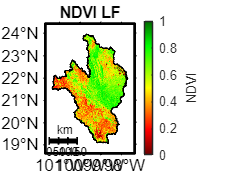

ndvi_prom = m_mean_3dpp(arr_ndvi_lf);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI LF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');


promedio = mean(ndvi_prom,"all","omitnan");
disp("Promedio: "+promedio);

Promedio: 0.54224




% exportgraphics(gca,"img/promedio_ndvi_lf.png",'Resolution',300) 



#### Mostrar el promedio de NDVI Savitzky-Golay de toda la serie

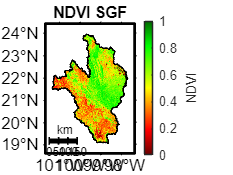

ndvi_prom = m_mean_3dpp(arr_ndvi_sgf);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI SGF",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');


promedio = mean(ndvi_prom,"all","omitnan");
disp("Promedio: "+promedio);

Promedio: 0.54223



% exportgraphics(gca,"img/promedio_ndvi_sgf.png",'Resolution',300) 

#### Mostrar el promedio de NDVI Media Juliana de toda la serie

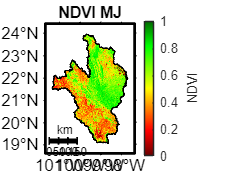

ndvi_prom = m_mean_3dpp(arr_ndvi_mj);
ndvi_prom(study_area==false)=nan;

f_draw_map(lon_mapa,lat_mapa,lon,lat,ndvi_prom,"NDVI MJ",[0 1],"NDVI","NDVI");
f_draw_kml(dir_data,kml_file,1,'k');


promedio = mean(ndvi_prom,"all","omitnan");
disp("Promedio: "+promedio);

Promedio: 0.54784



% exportgraphics(gca,"img/promedio_ndvi_sgf.png",'Resolution',300) 

